# Clearance

clc;
clear;
close all;

## VARIABLES

M = 16;       % Mic Number
L = 0.45;     % [m] Total Array Length
Fs = 8*1e3;   % [Hz] sampling frequency
c = 343;      % [m/s] speed of sound
d = L/(M-1);  % [m] mic distance

% anti-aliasing
max_freq = c/(2*d); % maximum carrier frequency
        %Here, max_freq~=5.7*10^3 Hz, and Nyquist frequency is fs/2 = 4 kHz


% stft window
Sz = 256;           % [samples] size of the rectangular window
Hop = 1;            % [samples] hopsize
fft_len = 1024;
theta_axis = -90:1:90;
theta_rad_axis = 0 : 2*pi/180 :  pi ;

%Adding the d<=lambda/2 condition with lambda the wavelength of the source
%signal --> STFT --> fc identification --> lambda computation --> checking
%if d = L/(M-1) <lambda/2

## FUNCTIONS

function [freqs, time_axis, freq_axis] = MyStft(in, samp_freq, wlen, fft_len) 
    %{
    Arg in : audiofile to analyze dimensions [len, n_chans]
    Arg samp_freq : sampling frequency we'll be using in Hz
    Arg wlen : length in samples of the window
    Arg fft_len : length of the total FFT, which will be halved at the end
                    to stay below Nyquist frequency

    Here, we are performing unitary hop size STFT

    Arg verbose : boolean flag to require plots
    Out freqs : 3D array containing, for each microphone source, the
                content of the fft of in for each applied window
    Out time_axis : array of dimension [1, num_wd] used to generate the
                    adequate time axis
    Out freq_axis : array of dimension [1, num_freq] used to generate the
                    adequate frequency axis, once again, num_freq is half the fft_len
                    (Nyquist frequency)
    %}   

    [len, n_chans] = size(in); 

    if (len < wlen)
        error("the input signal is shorter than the window ! ");
    end

    num_wd = floor(len-wlen)+1;

    in_trans = in.';
    y = zeros(fft_len, num_wd, n_chans);

    for i = 1:num_wd
        used_samps = i:i+wlen-1;            % range of application of the window
        wind_in = in_trans(:, used_samps);  % applying rectangular windowing on each channel

        freq_in = fft(wind_in, fft_len, 2); %Performing the STFT allong the columns of wind_in
        y(:,i,:) = freq_in.';               % the result is transposed to get the time on the rows
    end

    time_axis = (0:1:num_wd-1) * wlen/samp_freq;     % generating the time axis of the stft in ms
    %time_axis = (0:1:num_wd-num_wd/samp_freq) * 1/samp_freq;               
    freq_axis = 0 : samp_freq/fft_len : (samp_freq-samp_freq/fft_len)/2;    % generating the frequency axis of the stft, until Nyquist frequency
    freqs = y(1 : fft_len/2 , :, :);                                        % sampling theorem
end

function polarDoA_vid(name, norm_pspec, t, axis, time_vals, len, mic_len, num_mics, genme) 
    %{
        function used to generate the video of the evolution of the DoA in
        time both in a polar plot and as an arrow pointed from the centre
        of the array indicating the direction
    %}
    if (genme)
        vid = VideoWriter(name,"Motion JPEG 2000");
        disp("Generating polar doa video");
        vid.FrameRate = 20;
        open(vid);
        f = figure(200);
        f.WindowState = "maximized";
        for i = 1:len
             disp(['video frame #', num2str(i)]);
            subplot(2,1,1);
            polarplot(axis.*pi/180, norm_pspec(i,:));
            titleStr = ['Pseudo spectrum for window #' num2str(i), ' time : ', num2str(time_vals(i)), ' s' ];
            title(titleStr);
            hold off
            subplot(2,1,2)
            ylabel("meters [m]");
            xlabel("meters [m]");
            plot(linspace(-mic_len/2,mic_len/2,num_mics),zeros(1,num_mics),'LineStyle','none','Color','b','Marker', 'o', 'MarkerSize', 2, 'LineWidth', 5);
            xlim([-(mic_len/2+0.1),mic_len/2+0.1]);
            ylim([-0.2, 0.5]);
            hold on
            quiver(0,0,-sin(t(i)*pi/180)*0.3,cos(t(i)*pi/180)*0.3,'LineStyle','-','Color','r','LineWidth',1.5);%, 'AutoScaleFactor', 0.7);
            hold off
            frame = getframe(200);
            writeVideo(vid, frame);
            drawnow limitrate
        end
        close(vid);
    else 
        sprintf('polar doa video not genreated (genme = %i)', genme);
    end
end

## File extraction

[y, fs] = audioread("array_recordings.wav");

index_max_freq = floor( (max_freq/fs) * (fft_len) ); % index equivalent to the value of max_freq


## Computing the pseudo spectrum

[len, n_chans] = size(y);
steps = 200;
theta = zeros(steps,1);
step_len = floor(len/steps);
pseudo_tot = zeros(steps,length(theta_axis));

stft_len = floor(step_len-Sz)+1;
stft = zeros(fft_len/2, stft_len*steps, 2);

num_samp_t = (floor(step_len-Sz))*steps;

tot_t = (0:1:num_samp_t)./num_samp_t;
tot_t = tot_t.*len/fs;

% Extract the STFT results for each microphone channel

f.WindowState = "maximized";
for i = 1:steps
    disp(['computation loop #', num2str(i)]);
    [spectrum, time, freq] = MyStft( y((i-1)*step_len+1 : i*step_len, :), fs, Sz, fft_len);    % application of stft
    
    stft(:, (i-1)*stft_len+1 : i*stft_len, 1) = spectrum(:,:,1);  
    stft(:, (i-1)*stft_len+1 : i*stft_len, 2) = spectrum(:,:,4);  
    %tot_t((i-1)*stft_len+1 : i*stft_len)= time;
    %Checking the number of index where the estimation is relevant
    if ( index_max_freq >= length(freq) ) 
        index_max_freq = length(freq);
    end

    freq_bands = freq(4:2:index_max_freq);                                                  % arbitrarilly select some frequencies for the single band implementation
    cov_estimante_mat = zeros(M , M, length(freq_bands));                                   % allocate the covariance estimate matrix

    for f = freq_bands
        for t = 1:length(time)-1
            spec = squeeze(spectrum(freq==f, t, :));                                        % extracts the values of the stft at a specific sample and freq for all the mics
            cov_estimante_mat(:, :, freq_bands==f) = cov_estimante_mat(:,:,freq_bands==f) + spec*spec'/length(time); % calculates the covariance estimate matrix
        end
    end
    
    pseudo = zeros(length(freq_bands), length(theta_axis));                                 % allocates the pseudo spectrum matrix
    a_vec = zeros(M,1);

    for f = 1:length(freq_bands)
        for p = 1:length(theta_axis)
            a_vec = exp(-1i*2*pi*freq_bands(f)*d*sin(theta_axis(p)*pi/180) .* (0:1:M-1).'/c);
            pseudo(f,p) = a_vec' * cov_estimante_mat(:, :, f) * a_vec/ M^2; % calculates the pseudo spectrum matrix
        end
    end
    pseudo_avg = sum(pseudo, 1)/length(freq_bands); % averages the pseudo spectrums for the various freq bands
    pseudo_avg_abs = abs(pseudo_avg);
    pseudo_tot(i,:) = pseudo_avg;
        
    [~, idx] = max(abs(pseudo_avg)); % finds theta as the max of the magnitude of the averaged pseudo spectrums
    theta(i) = theta_axis(idx);
end

computation loop #1
computation loop #2
computation loop #3
computation loop #4
computation loop #5
computation loop #6
computation loop #7
computation loop #8
computation loop #9
computation loop #10
computation loop #11
computation loop #12
computation loop #13
computation loop #14
computation loop #15
computation loop #16
computation loop #17
computation loop #18
computation loop #19
computation loop #20
computation loop #21
computation loop #22
computation loop #23
computation loop #24
computation loop #25
computation loop #26
computation loop #27
computation loop #28
computation loop #29
computation loop #30
computation loop #31
computation loop #32
computation loop #33
computation loop #34
computation loop #35
computation loop #36
computation loop #37
computation loop #38
computation loop #39
computation loop #40
computation loop #41
computation loop #42
computation loop #43
computation loop #44
computation loop #45
computation loop #46
computation loop #47
computation loop #48
c

steps_axis = linspace(0,len/fs,steps);  %[s]

[~, idxM] = max(theta);
[~, idxm] = min(theta);
disp(['Maximum theta :', num2str(theta(idxM)), ' at time ', num2str(steps_axis(idxM)), ' s']);

Maximum theta :32 at time 14.733 s


disp(['Maximum theta :', num2str(theta(idxm)), ' at time ', num2str(steps_axis(idxm)), ' s']);

Maximum theta :-64 at time 9.1804 s


## Generating the video of the acquired pseudo spectrum

norm_pseudo_tot = abs(pseudo_tot);
norm_pseudo_tot = norm_pseudo_tot./max(norm_pseudo_tot, [], 2);
rotated_theta = mod(theta_axis*pi/180 + pi/2, 2*pi);

polarDoA_vid("polar_doa", norm_pseudo_tot, theta, theta_axis, steps_axis, steps, L, M, false);

## Other plots

disp(tot_t(1))

     0



disp(tot_t(end))

   14.7330



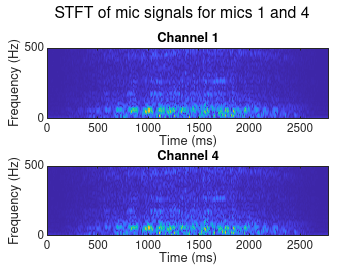


figure(12);
subplot(2, 1, 1);
imagesc(tot_t, freq, abs(stft(:, :, 1)));
axis xy;
title(sprintf("Channel %d", 1));
xlabel("Time (ms)");
ylabel("Frequency (Hz)")
ylim([freq(1), 500]);
subplot(2, 1, 2);
imagesc(tot_t, freq, abs(stft(:, :, 2)));
axis xy;
title(sprintf("Channel %d", 4));
xlabel("Time (ms)");
ylabel("Frequency (Hz)");
ylim([freq(1), 500]);
sgtitle(sprintf("STFT of mic signals for microphones 1 and 4"));

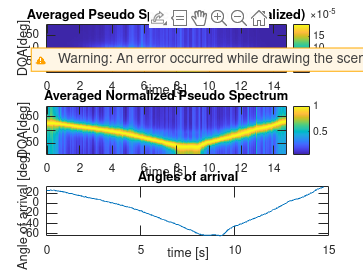


figure(13);
subplot(3,1,1);
imagesc(steps_axis,theta_axis, abs(pseudo_tot'));
ylabel("DOA[deg]");
xlabel("time [s]");
colorbar;
axis xy;
title("Averaged Pseudo Spectrum (non normalized)");

subplot(3,1,2);
imagesc(steps_axis,theta_axis, norm_pseudo_tot');
ylabel("DOA[deg]");
xlabel("time [s]");
colorbar;
axis xy;
title("Averaged Normalized Pseudo Spectrum");

subplot(3,1,3);
plot(steps_axis, theta);
ylabel("Angle of arrival [deg]");
xlabel("time [s]");
title("Angles of arrival");

## Plot quiver plot

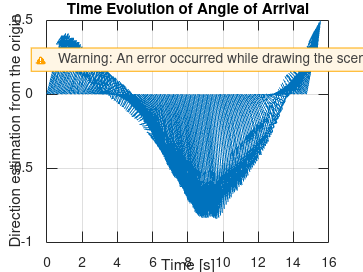

% Calculate x and y components of vectors
x = cos(theta*pi/180); % x component
y = sin(theta*pi/180); % y component

figure();
quiver(steps_axis', zeros(size(steps_axis)), x, y);%, 'Color', 'b', 'LineStyle', '--', 'AutoScaleFactor', 0.5);
xlabel('Time [s]');
ylabel('Direction estimation from the origin');
title('Time Evolution of Angle of Arrival');

%set(gca, 'XLim', [min(steps_axis), max(steps_axis)], 'YLim', [-1.2, 1.2], 'LineWidth', 1.5, 'TickLength', [0.02, 0.02]);
grid on;